# Exercise 7

## Exercise 7.3

X = 1:6

X =      1     2     3     4     5     6


Y =  [16 18 21 17 15 12]

Y =     16    18    21    17    15    12


lagrange(X, Y, 1:6)

ans =     16    18    21    17    15    12


## Exercise 7.3.1

x = 3:1/100:6

x =     3.0000    3.0100    3.0200    3.0300    3.0400    3.0500    3.0600    3.0700    3.0800    3.0900    3.1000    3.1100    3.1200    3.1300    3.1400    3.1500    3.1600    3.1700    3.1800    3.1900    3.2000    3.2100    3.2200    3.2300    3.2400    3.2500    3.2600    3.2700    3.2800    3.2900    3.3000    3.3100    3.3200    3.3300    3.3400    3.3500    3.3600    3.3700    3.3800    3.3900    3.4000    3.4100    3.4200    3.4300    3.4400    3.4500    3.4600    3.4700    3.4800    3.4900



X = [3 5 1 4 2 6]

X =      3     5     1     4     2     6


Y = [21 15 16 17 18 12]

Y =     21    15    16    17    18    12



lagrange(X, Y, x)

ans =    21.0000   20.9841   20.9673   20.9497   20.9314   20.9121   20.8921   20.8713   20.8498   20.8274   20.8043   20.7804   20.7558   20.7304   20.7043   20.6775   20.6500   20.6218   20.5929   20.5633   20.5331   20.5022   20.4706   20.4384   20.4056   20.3722   20.3382   20.3036   20.2684   20.2326   20.1963   20.1594   20.1220   20.0841   20.0457   20.0067   19.9673   19.9274   19.8870   19.8462   19.8050   19.7633   19.7212   19.6787   19.6359   19.5926   19.5490   19.5050   19.4607   19.4160


## Exercise 7.4

x = 1:1/100:6;

X = 1:6;
Y = [16 18 21 17 15 12];
T = divided_differences(X, Y)

T =    16.0000         0         0         0         0         0
   18.0000    2.0000         0         0         0         0
   21.0000    3.0000    0.5000         0         0         0
   17.0000   -4.0000   -3.5000   -1.3333         0         0
   15.0000   -2.0000    1.0000    1.5000    0.7083         0
   12.0000   -3.0000   -0.5000   -0.5000   -0.5000   -0.2417



y = divided_eval(X, T, x)

y =    16.0000   15.8903   15.7853   15.6851   15.5894   15.4984   15.4118   15.3295   15.2516   15.1779   15.1084   15.0429   14.9814   14.9238   14.8701   14.8201   14.7738   14.7312   14.6921   14.6565   14.6243   14.5954   14.5698   14.5473   14.5281   14.5118   14.4986   14.4883   14.4809   14.4762   14.4744   14.4751   14.4785   14.4844   14.4929   14.5037   14.5169   14.5324   14.5502   14.5701   14.5922   14.6163   14.6425   14.6706   14.7007   14.7326   14.7663   14.8017   14.8388   14.8776


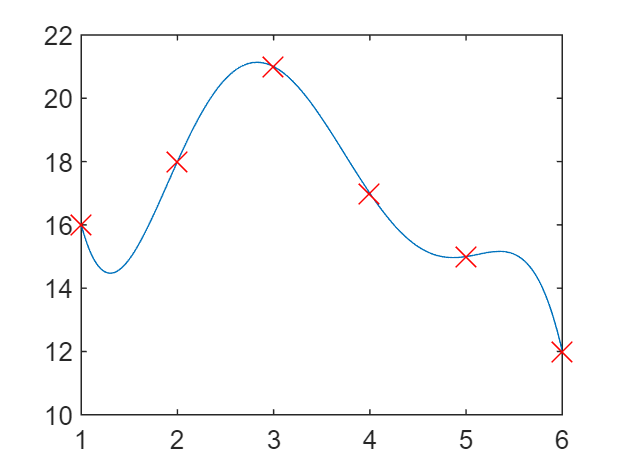


figure
plot(x, y)
hold on

plot(X, Y, 'xr', MarkerSize=10)

## Exercise 7.4.1

X = [0, pi/2, pi/6, pi/4]

X =          0    1.5708    0.5236    0.7854


Y = cos(X)

Y =     1.0000    0.0000    0.8660    0.7071



x = min(X):1/100:max(X);

T = divided_differences(X, Y)

T =     1.0000         0         0         0
    0.0000   -0.6366         0         0
    0.8660   -0.8270   -0.3636         0
    0.7071   -0.6070   -0.2801    0.1063



y = divided_eval(X, T, x)

y =     1.0000    1.0002    1.0002    1.0001    0.9999    0.9996    0.9992    0.9987    0.9981    0.9973    0.9964    0.9955    0.9944    0.9932    0.9919    0.9905    0.9889    0.9873    0.9856    0.9837    0.9818    0.9797    0.9776    0.9753    0.9730    0.9705    0.9679    0.9653    0.9625    0.9597    0.9567    0.9536    0.9505    0.9472    0.9439    0.9404    0.9369    0.9332    0.9295    0.9257    0.9218    0.9178    0.9137    0.9095    0.9052    0.9008    0.8964    0.8918    0.8872    0.8825


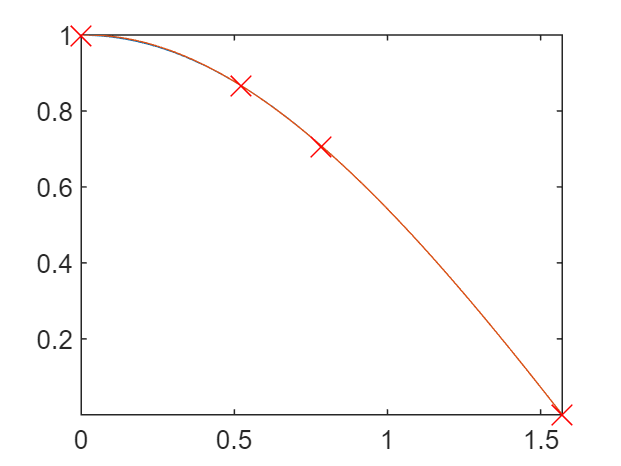


figure
fplot(@(x) cos(x), [0, pi/4])
hold on
plot(x, y)

plot(X, Y, 'xr', MarkerSize=10)